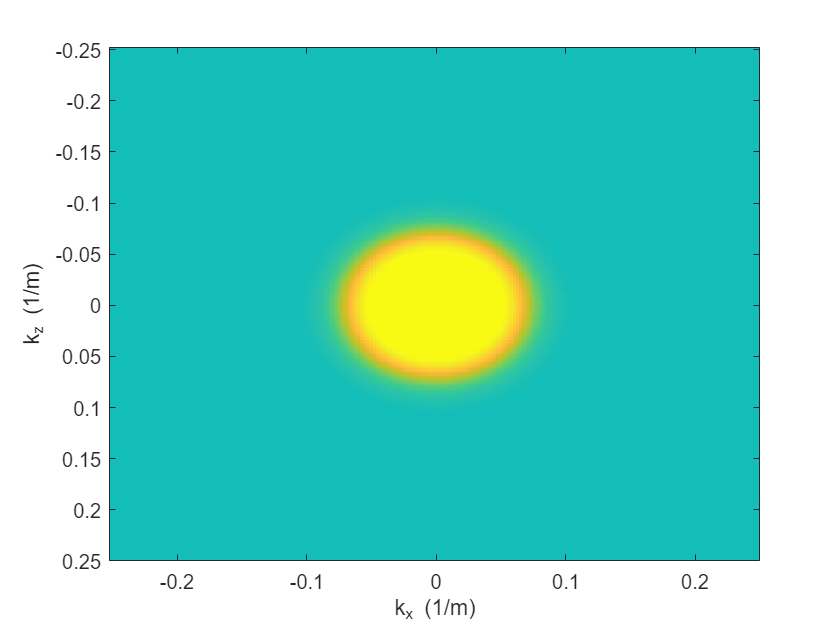

%computation domain
nz=200; nx=200;
h=12.5; %meters

%time steps
nt=2000; %1000;
dt=0.0015; %sec

%peak frequency
fp=8; %Hz

%sampling frequancy
fs=1/dt;

y_time=linspace(0,nt*dt,nt);
x_distance=linspace(0,nx*h,nx)/1000;
z_distance=linspace(0,nz*h,nx)/1000;

%velocity range
% vp=1500*ones(nz,nx);
% vp(3/5*nz:end,:)=2000;



nz_m=281; nx_m=1361;
fileID = fopen('vp.12.5m');
vp0 = fread(fileID,'single');
vp1 = reshape(vp0,nz_m,nx_m);
% vp = vp1(1:nx,600:600+nz-1);
vp = vp1(1:nz,600:600+nx-1)+500;

fileID = fopen('rho.12.5m');
rho0 = fread(fileID,'single');
rho1 = reshape(rho0,nz_m,nx_m);
rho = rho1(1:nz,600:600+nx-1)/1000;
% rho = 1;
% rho = ones(nz,nx);
% rho(3/5*nz:end,:)= 2;
%cmin=625.;
%cmax=1750.;
Q=50;
%Q=1000;

% vp=2000*ones(nz,nx);
vs=vp./1.7;
% rho=1;

%source location
isz=1; isx=50;


[xp1, x, xm1, zp1, z, zm1] = initialize_D(nx,nz);

kx = 2*pi*(-nx/2:nx/2-1) / (h*nx);   % kx in rad/m
kz = 2*pi*(-nz/2:nz/2-1) / (h*nz);   % kz in rad/m

[KX, KZ] = meshgrid(kx, kz);
K = sqrt(KX.^2 + KZ.^2);              % absolute wavenumber

k_cut = 2*pi*fp/min(vp,[],"all")*2;  % cutoff wavenumber (rad/m)
% mask = double(K <= k_cut);             % low-pass filter mask
mask = zeros(size(K));

% 完全保留区域：K <= k_cut
mask(K <= k_cut) = 1;

% 过渡区域：K > k_cut，平滑衰减
sigma_filter=0.5;
idx = (K > k_cut);
mask(idx) = exp( - ((K(idx) - k_cut) / (sigma_filter * k_cut)).^2 );

figure
imagesc(kz,kx,mask)
clim([-1 1]) 
xlabel('k_x (1/m)'); ylabel('k_z (1/m)');

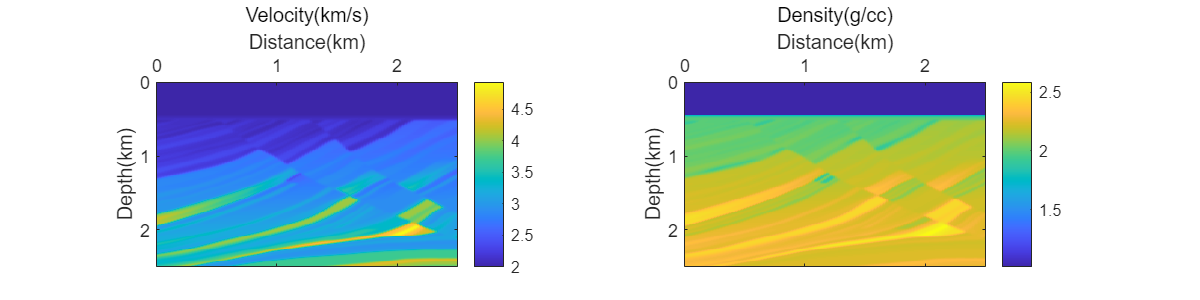

figure('Position',[800 800 800 200])
subplot(1,2,1)
imagesc(x_distance,z_distance,vp/1000)
colorbar
title('Vp')
xlabel('Distance(km)'); ylabel('Depth(km)');set(gca,'xaxisLocation','top');
colormap('jet')
clim([1.6,4.7])
hcb=colorbar;
hcb.Title.String = "km/s";
subplot(1,2,2)
imagesc(x_distance,z_distance,rho)
colorbar
title('Density')
xlabel('Distance(km)'); ylabel('Depth(km)');set(gca,'xaxisLocation','top');

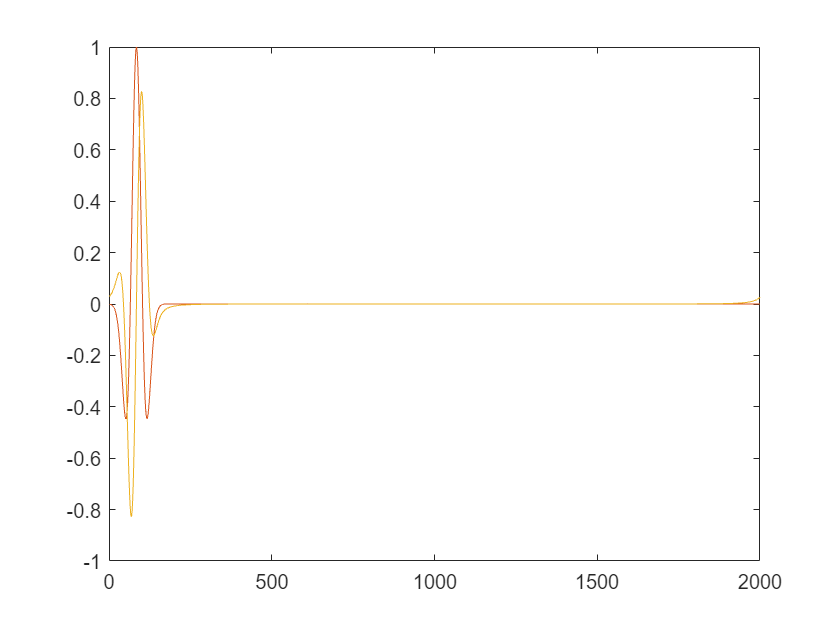

clim([1.8,2.9])
hcb=colorbar;
hcb.Title.String = "g/cc";

%source time function
figure
wl=ricker(fp,dt,nt);
plot(wl); hold on; 
plot(real(hilbert(wl)));
plot(imag(hilbert(wl)));

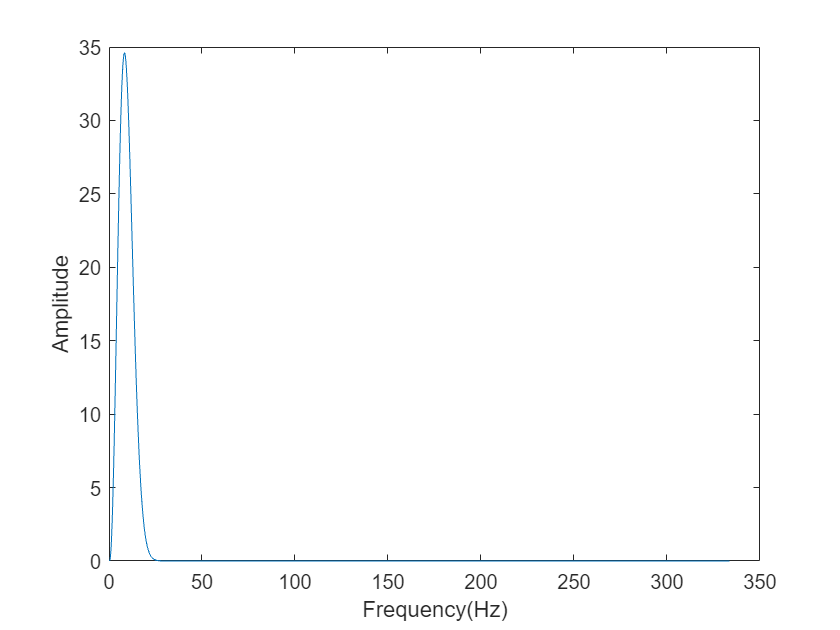

spectrum_wl = fft(wl');
figure
plot(1/(dt*nt)*(1:floor(nt/2+1)),abs(spectrum_wl(1:floor(nt/2+1))));
xlabel('Frequency(Hz)'); ylabel('Amplitude')



% shotgathers_Dispersion=modeling_AC_exact({vp,vs,rho,Q,mask},[1 0],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1, h});
% shotgathers_Disspitation=modeling_AC_exact({vp,vs,rho,Q,mask},[0 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1, h});
shotgathers=modeling_DTCV({vp,vs,rho,Q,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1, h});

Has Dispersion
Has Dissipation


it = 100

t_one_step = 0.0042

ans = -5.3915e-09 - 2.1623e-09i

ans = 6.2934 + 6.9048i

it = 200

t_one_step = 0.0040

ans = 2.0309e-08 - 2.6963e-09i

ans = 1.5890 + 0.4250i

it = 300

t_one_step = 0.0033

ans = -3.3642e-07 + 3.9399e-07i

ans = 1.5871 + 0.2640i

it = 400

t_one_step = 0.0039

ans = -1.9147e-06 + 4.3068e-06i

ans = 1.3903 - 0.0262i

it = 500

t_one_step = 0.0041

ans = -9.4100e-07 + 3.5103e-06i

ans = 1.2282 + 0.4455i

it = 600

t_one_step = 0.0050

ans = 1.4552e-05 - 2.6647e-06i

ans = 1.2680 - 0.4595i

it = 700

t_one_step = 0.0040

ans = -6.6259e-05 + 1.9888e-05i

ans = 0.8396 + 0.3985i

it = 800

t_one_step = 0.0036

ans = -8.5499e-05 - 6.7209e-05i

ans = -0.3958 + 0.0630i

it = 900

t_one_step = 0.0037

ans = 4.5842e-05 - 5.8005e-05i

ans = -0.3176 + 0.0669i

it = 1000

t_one_step = 0.0046

ans = -2.6890e-05 - 1.6221e-05i

ans = -0.1847 + 0.0699i

it = 1100

t_one_step = 0.0060

ans = 4.7398e-05 + 7.6648e-06i

ans = -0.1361 + 0.0157i

it = 1200

t_one_step = 0.0034

ans = 1.8457e-06 - 1.7384e-05i

ans = 0.0050 - 0.0957i

it = 1300

t_one_step = 0.0040

ans = -6.6291e-06 + 1.6622e-05i

ans = 0.0211 - 0.0954i

it = 1400

t_one_step = 0.0038

ans = 2.9523e-05 - 1.0097e-06i

ans = -0.0574 - 0.0313i

it = 1500

t_one_step = 0.0034

ans = 1.8681e-05 - 1.2354e-05i

ans = -0.0132 - 0.0570i

it = 1600

t_one_step = 0.0036

ans = 5.9803e-06 + 6.8694e-06i

ans = 0.0347 - 0.0488i

it = 1700

t_one_step = 0.0038

ans = 8.2174e-06 + 3.0915e-06i

ans = 0.0335 - 0.0396i

it = 1800

t_one_step = 0.0035

ans = 1.3813e-05 - 9.8221e-06i

ans = 0.0439 - 0.0203i

it = 1900

t_one_step = 0.0036

ans = -1.2592e-05 + 1.5759e-06i

ans = 0.0243 + 0.0280i

it = 2000

t_one_step = 0.0035

ans = 1.0100e-06 - 1.6304e-06i

ans = 0.0015 + 0.2709i

t_sum = 8.2955

t_average = 4.1477

shotgathers_exact=modeling_AC_exact({vp,vs,rho,Q,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1, h});

Has Dispersion
Has Dissipation


it = 100

t_one_step = 0.3159

ans = 0

ans = 6.3749 + 6.8510i

it = 200

t_one_step = 0.5703

ans = 0

ans = 1.5638 + 0.5173i

it = 300

t_one_step = 0.8405

ans = 1.4572e-07 - 7.2596e-08i

ans = 1.5891 + 0.2482i

it = 400

t_one_step = 1.0891

ans = 1.6838e-06 - 2.1440e-07i

ans = 1.3756 - 0.0512i

it = 500

t_one_step = 1.3564

ans = -5.6023e-06 - 3.9336e-06i

ans = 1.2254 + 0.4160i

it = 600

t_one_step = 1.6168

ans = 3.2898e-06 - 7.3806e-06i

ans = 1.2258 - 0.4824i

it = 700

t_one_step = 1.8799

ans = -1.1398e-04 + 3.6801e-05i

ans = 0.8037 + 0.4300i

it = 800

t_one_step = 2.1350

ans = -7.3846e-06 - 4.3481e-07i

ans = -0.3929 + 0.0669i

it = 900

t_one_step = 2.3974

ans = -1.6095e-05 + 4.6896e-05i

ans = -0.3250 + 0.0268i

it = 1000

t_one_step = 2.6567

ans = 1.5696e-05 - 8.3401e-06i

ans = -0.1900 + 0.0801i

it = 1100

t_one_step = 2.9268

ans = 1.7365e-05 - 7.5091e-05i

ans = -0.1280 + 0.0544i

it = 1200

t_one_step = 3.1819

ans = -1.6233e-06 + 8.9680e-06i

ans = -0.0350 - 0.0926i

it = 1300

t_one_step = 3.4333

ans = -2.7173e-07 - 6.4423e-07i

ans = 0.0254 - 0.1013i

it = 1400

t_one_step = 3.6857

ans = 1.4857e-05 + 1.0904e-05i

ans = -0.0531 - 0.0592i

it = 1500

t_one_step = 3.9395

ans = -7.2843e-06 + 6.4354e-06i

ans = -0.0019 - 0.0600i

it = 1600

t_one_step = 4.1944

ans = 1.0799e-05 + 7.1285e-06i

ans = 0.0286 - 0.0596i

it = 1700

t_one_step = 4.4408

ans = 3.2367e-06 + 9.5336e-07i

ans = 0.0206 - 0.0584i

it = 1800

t_one_step = 4.6897

ans = 1.0334e-05 - 2.4567e-06i

ans = 0.0460 - 0.0230i

it = 1900

t_one_step = 4.9410

ans = 2.5028e-06 + 4.6633e-07i

ans = 0.0134 + 0.0410i

it = 2000

t_one_step = 5.2664

ans = -1.5489e-05 - 9.1724e-06i

ans = 0.0073 + 0.2650i

t_sum = 5.2542

t_average = 2.6271

shotgathers_GSLS=modeling_GSLS({vp,rho},{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1, h});

it = 100

t_one_step = 8.1871

ans = -1.2905

ans = 6.5476

it = 200

t_one_step = 9.2312

ans = -0.8323

ans = 1.6977

it = 300

t_one_step = 9.6495

ans = -0.7443

ans = 1.6716

it = 400

t_one_step = 10.0611

ans = -0.6050

ans = 1.4590

it = 500

t_one_step = 10.4087

ans = -0.7158

ans = 1.3582

it = 600

t_one_step = 10.9040

ans = -0.6171

ans = 1.3719

it = 700

t_one_step = 11.3036

ans = -0.3744

ans = 0.9734

it = 800

t_one_step = 11.7168

ans = -0.4240

ans = 0.2009

it = 900

t_one_step = 12.0723

ans = -0.3792

ans = 0.1605

it = 1000

t_one_step = 12.4752

ans = -0.2157

ans = 0.1495

it = 1100

t_one_step = 12.8973

ans = -0.1566

ans = 0.0991

it = 1200

t_one_step = 13.2191

ans = -0.1037

ans = 0.0837

it = 1300

t_one_step = 13.5914

ans = -0.0717

ans = 0.0675

it = 1400

t_one_step = 13.9295

ans = -0.0774

ans = 0.0448

it = 1500

t_one_step = 14.2967

ans = -0.0556

ans = 0.0619

it = 1600

t_one_step = 14.6746

ans = -0.0461

ans = 0.0720

it = 1700

t_one_step = 15.0345

ans = -0.0413

ans = 0.0688

it = 1800

t_one_step = 15.3375

ans = -0.0371

ans = 0.0650

it = 1900

t_one_step = 15.7210

ans = -0.0350

ans = 0.0481

it = 2000

t_one_step = 16.1493

ans = -0.0349

ans = 0.0181

t_sum = 8.4383

t_average = 4.2191

shotgathers_noVis=modeling_AC({vp,vs,rho,Q,mask},[0 0],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1, h});

it = 100

t_one_step = 0.0023

ans = 0

ans = 6.5769 + 7.3505i

it = 200

t_one_step = 0.0031

ans = 0

ans = 1.8571 + 0.4146i

it = 300

t_one_step = 0.0027

ans = -2.0150e-44 + 5.3995e-43i

ans = 1.9299 + 0.5747i

it = 400

t_one_step = 0.0027

ans = -1.3880e-12 + 2.7761e-11i

ans = 1.8101 + 0.1835i

it = 500

t_one_step = 0.0031

ans = -4.0138e-06 + 4.7102e-06i

ans = 1.7297 + 0.9008i

it = 600

t_one_step = 0.0037

ans = -3.2737e-06 + 6.4363e-06i

ans = 1.5459 - 0.9473i

it = 700

t_one_step = 0.0025

ans = 6.3207e-07 - 3.3422e-05i

ans = 1.4532 + 0.4523i

it = 800

t_one_step = 0.0032

ans = -8.3208e-05 - 7.1910e-05i

ans = -0.7228 - 0.0051i

it = 900

t_one_step = 0.0024

ans = 3.8616e-05 - 7.4402e-05i

ans = -0.6276 + 0.3827i

it = 1000

t_one_step = 0.0027

ans = 2.1405e-05 - 4.5079e-05i

ans = -0.1868 + 0.3480i

it = 1100

t_one_step = 0.0042

ans = -8.0367e-06 - 9.9915e-06i

ans = -0.3046 - 0.0439i

it = 1200

t_one_step = 0.0024

ans = -1.4211e-05 + 2.2492e-05i

ans = -0.1287 - 0.1734i

it = 1300

t_one_step = 0.0026

ans = -1.1387e-05 + 4.2362e-07i

ans = -0.0430 - 0.3020i

it = 1400

t_one_step = 0.0026

ans = -7.7091e-06 - 9.3435e-06i

ans = -0.1944 - 0.0551i

it = 1500

t_one_step = 0.0025

ans = -6.1863e-05 + 1.0550e-05i

ans = -0.0764 - 0.1432i

it = 1600

t_one_step = 0.0026

ans = 1.1838e-05 + 5.6342e-06i

ans = 0.1022 - 0.1870i

it = 1700

t_one_step = 0.0026

ans = -8.4737e-06 - 3.4821e-05i

ans = 0.0878 - 0.1985i

it = 1800

t_one_step = 0.0026

ans = 1.6075e-05 - 5.5206e-06i

ans = 0.1922 + 0.0659i

it = 1900

t_one_step = 0.0040

ans = -5.6248e-07 + 3.4547e-06i

ans = 0.1541 + 0.1679i

it = 2000

t_one_step = 0.0028

ans = -3.6691e-06 - 2.6706e-06i

ans = 0.0148 + 0.2718i

t_sum = 5.5503

t_average = 2.7752

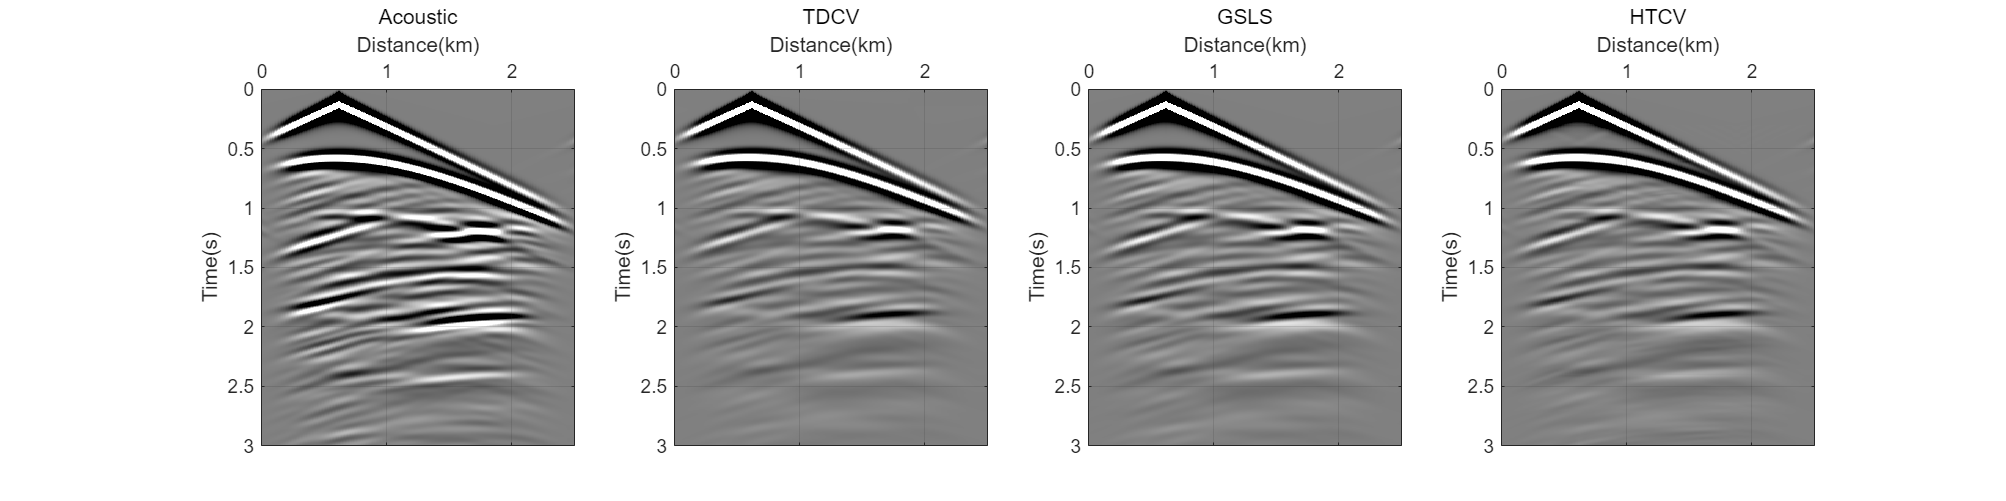

% figure('Position',[400 400 3200 800])
% clip=0.1;
% subplot(1,4,1)
% imagesc(real(shotgathers_noVis)); 
% colormap('gray')
% clim([-clip clip]) 
% title('No Visco')
% xlabel('offshot'); ylabel('time'); grid on;
% 
% subplot(1,4,2)
% imagesc(real(shotgathers_Dispersion)); 
% colormap('gray')
% clim([-clip clip]) 
% title('Only Dispersion')
% xlabel('offshot'); ylabel('time'); grid on;
% 
% subplot(1,4,3)
% imagesc(real(shotgathers_Disspitation)); 
% colormap('gray')
% clim([-clip clip]) 
% title('Only Dissipitation')
% xlabel('offshot'); ylabel('time'); grid on;
% 
% subplot(1,4,4)
% imagesc(real(shotgathers_exact)); 
% colormap('gray')
% % colorbar
% % axis equal
% % axis tight
% clim([-clip clip]) 
% title('Both')
% xlabel('offshot'); ylabel('time'); grid on;



figure('Position',[400 400 3200 800])
clip=0.1;
subplot(1,4,1)
imagesc(x_distance,y_time,real(shotgathers_noVis)); 
colormap('gray')
clim([-clip clip]) 
title('Acoustic')
xlabel('Distance(km)'); ylabel('Time(s)');
set(gca,'xaxisLocation','top')
grid on;

subplot(1,4,2)
imagesc(x_distance,y_time,real(shotgathers)); 
colormap('gray')
clim([-clip clip]) 
title('TDCV')
xlabel('Distance(km)'); ylabel('Time(s)');
set(gca,'xaxisLocation','top')
grid on;

subplot(1,4,3)
imagesc(x_distance,y_time,real(shotgathers_GSLS)); 
colormap('gray')
% colorbar
% axis equal
% axis tight
clim([-clip clip]) 
title('GSLS')
xlabel('Distance(km)'); ylabel('Time(s)');
set(gca,'xaxisLocation','top')
grid on;
subplot(1,4,4)
imagesc(x_distance,y_time,real(shotgathers_exact)); 
colormap('gray')
clim([-clip clip]) 
title('HTCV')
xlabel('Distance(km)'); ylabel('Time(s)');
set(gca,'xaxisLocation','top')
grid on;

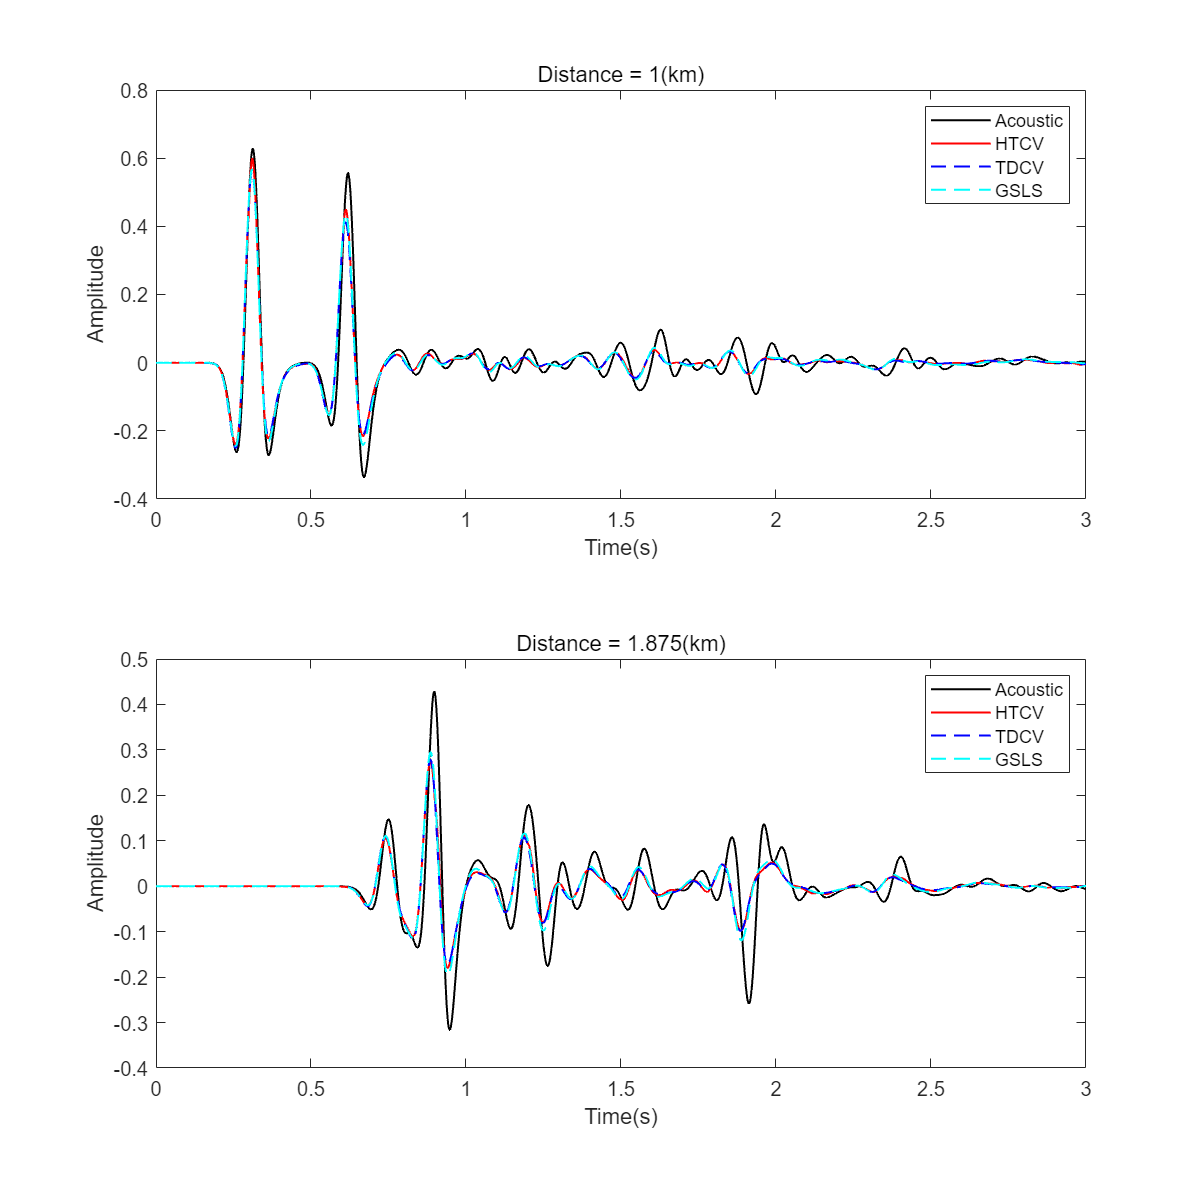


figure('Position',[400 400 800 800])
location1 = 80;
location2 = 150;
subplot(2,1,1)
plot(y_time, real(shotgathers_noVis(:,location1)), '-','Color', 'k','LineWidth',1); hold  on;
plot(y_time, real(shotgathers_exact(:,location1)),'-','Color', 'red','LineWidth',1); hold  on;
plot(y_time, real(shotgathers(:,location1)),'--','Color', 'c','LineWidth',1); hold  on;
plot(y_time, real(shotgathers_GSLS(:,location1)),'--','Color', 'm','LineWidth',1)
% set(gca, 'YDir', 'reverse');
title(['Distance = ' , num2str(location1*h/1000),'(km)'])
xlabel('Time(s)')
ylabel('Amplitude')
legend('Acoustic','HTCV','TDCV', 'GSLS')
subplot(2,1,2)
plot(y_time, real(shotgathers_noVis(:,location2)),'Color', 'k','LineWidth',1); hold  on;
plot(y_time, real(shotgathers_exact(:,location2)),'-','Color', 'red','LineWidth',1); hold  on;
plot(y_time, real(shotgathers(:,location2)),'--','Color', 'c','LineWidth',1); hold  on;
plot(y_time, real(shotgathers_GSLS(:,location2)),'--','Color', 'm','LineWidth',1)
title(['Distance = ' , num2str(location2*h/1000),'(km)'])
xlabel('Time(s)')
ylabel('Amplitude')
% set(gca, 'YDir', 'reverse');
legend('Acoustic','HTCV','TDCV', 'GSLS')

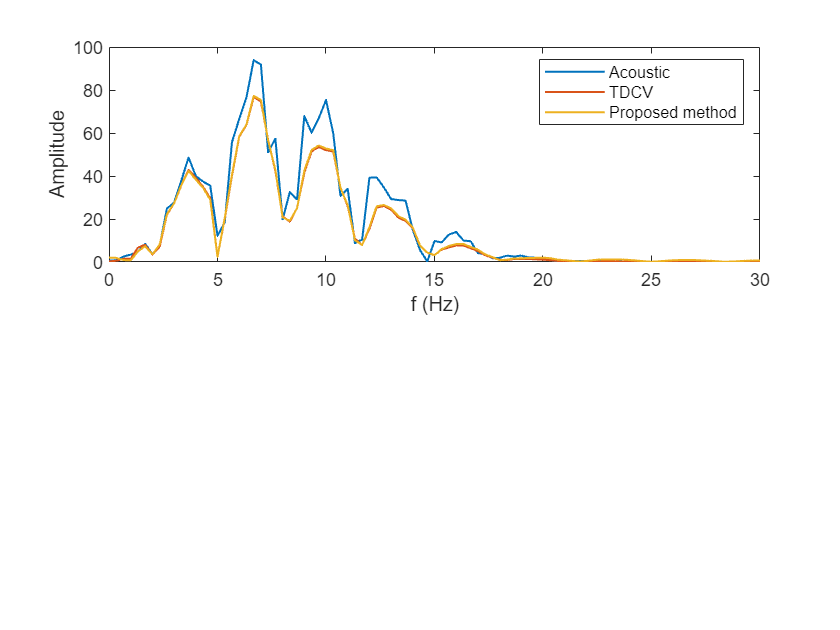


trace_fft_noVis1=fftshift(fft(shotgathers_noVis(:,location1)));
trace_fft_TDCV1=fftshift(fft(shotgathers(:,location1)));
trace_fft_exact1=fftshift(fft(shotgathers_exact(:,location1)));
fre_range = fs/nt*(-nt/2:nt/2-1);
figure;
subplot(2,1,1);
plot(fre_range,abs(trace_fft_noVis1),'LineWidth',1); hold on;
plot(fre_range,abs(trace_fft_TDCV1),'LineWidth',1); hold on;
plot(fre_range,abs(trace_fft_exact1),'LineWidth',1); 
xlim([0,30])
xlabel('f (Hz)'); ylabel('Amplitude');
legend('Acoustic','TDCV','Proposed method', 'GSLS')

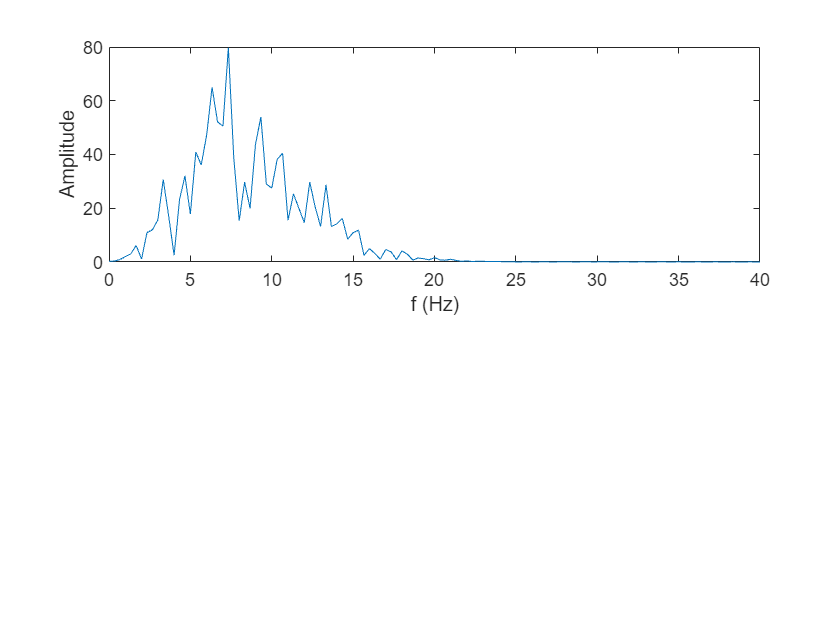


trace_fft2=fftshift(fft(shotgathers_noVis(:,location2)));
figure;
subplot(2,1,1);
plot(fre_range,abs(trace_fft2));
xlim([0,40])
xlabel('f (Hz)'); ylabel('Amplitude');

function shotgathers=modeling_AC(model,mode,spatial_grid,source,temporal_grid,space_grid)
    
    %model
    vp=model{1};
    vs=model{2};
    rho=model{3};
    Q=model{4};
    mask=model{5};

    % xp1=space_grid{1};
    % x=space_grid{2};
    % xm1=space_grid{3};
    % zp1=space_grid{4};
    % z=space_grid{5};
    % zm1=space_grid{6};

    % mu = vs^2*rho;
    kappa = vp.^2.*rho;
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    wl_hilbert=hilbert(source{1});
    src=wl_hilbert;
    % src = source{1};
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    
    n_absorb = 40;
    absorbtion = 0.95;
    
    absorb = get_absorbing_bc(absorbtion, n_absorb, nx, nz);

    p=complex(zeros(nz,nx));
    pold=complex(zeros(nz,nx));
    pnew=complex(zeros(nz,nx));
    shotgathers=complex(zeros(nt,nx));

    %auxiliary variables
    r=vp*dt; r2=r.*r;
        
    % %smoothing
    sigma=2;
    ismth_start=ceil(2/fp/dt);
    ismth=200;
    
    %Mur ABC
    % [c1,c2,c3,c4]=abc_coef(r,r2);
    rhoi = 1./rho;

    t_start = tic;
    for it=1:nt
        tic
        %if(mod(it,100)==0) disp(it), end
        if(mod(it,100)==0)
            it,t_one_step,min(pnew(:,:),[],'all','includenan'),max(pnew(:,:),[],'all','includenan')
        end
        
        p(:,:) = p(:,:).*absorb(:,:);
        pold(:,:) = pold(:,:).*absorb(:,:);

        % p(end,:) = p(2,:);

        p(izs,ixs) = p(izs,ixs)+src(it);
        acceleration_dx = rhoi.*(D(0,1,p, space_grid));
        acceleration_dz = rhoi.*(D(1,1,p, space_grid));

        % acceleration_dx(end,:) = acceleration_dx(2,:);
        % acceleration_dz(end,:) = acceleration_dz(2,:);

        pnew = 2*p - pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,space_grid) ...
                                                   + D(1,-1,acceleration_dz,space_grid));

        pold(:,:) = p(:,:) ;
        p(:,:)  = pnew(:,:) ;

        shotgathers(it,:) = p(1,:);

        t_one_step=toc;
    end

    t_sum = toc(t_start)
    t_average=t_sum/nt *1000

end

function shotgathers=modeling_DTCV(model,mode,spatial_grid,source,temporal_grid,space_grid)
    
    %model
    vp=model{1};
    vs=model{2};
    rho=model{3};
    Q=model{4};
    mask=model{5};

    % xp1=space_grid{1};
    % x=space_grid{2};
    % xm1=space_grid{3};
    % zp1=space_grid{4};
    % z=space_grid{5};
    % zm1=space_grid{6};

    % mu = vs^2*rho;
    kappa = vp.^2.*rho;
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    wl_hilbert=hilbert(source{1});
    src=wl_hilbert;
    % src = source{1};
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    

    %KF model
    if mode(1)~=0
        % a=5.7356; b=-762.1606; d=4.6054e4;
        a = 3.7801; b=-110.6870; d=1111.5;
        % a = 4.39719303795659 ; b =  -195.950557022390;   d = 2674.02350872252;
        disp('Has Dispersion');
    else
        a=0.; b=0.; d=0.;
        disp('NO Dispersion');
    end

    if mode(2)~=0
        e=1; disp('Has Dissipation');
    else
        e=0;  disp('NO Dissipation');
    end

    c1 = 1 - 2*a/pi./Q;
    c2 = 2*b/pi./Q;
    c3 = 2*d/pi./Q;
    c4 = e*1./(rho.*vp.*Q);



    % C1= (1 -2*a/pi/Q -e*1i/Q -b*1i/pi/Q*dt); C1=1./C1;
    % C2= (1 -2*a/pi/Q -e*1i/Q              -d/pi/Q*dt*dt)*2;
    % C3=-(1 -2*a/pi/Q -e*1i/Q +b*1i/pi/Q*dt);



    coef1 = (2*c1 + complex(0,c2*dt) - c3*dt^2)./c1;
    coef2 = -(c1 + complex(0,c2*dt))./c1;
    coef3 = rho.*vp.^2*dt^2./c1;

    n_absorb = 40;
    absorbtion = 0.95;
    
    absorb = get_absorbing_bc(absorbtion, n_absorb, nx, nz);

    % coef1 = (2*c1 - c3*dt^2)./(c1-complex(0,c2.*dt/2));
    % coef2 = -(c1 + complex(0,c2*dt/2))./(c1-complex(0,c2.*dt/2));
    % coef3 = rho.*vp^2*dt^2./(c1-complex(0,c2.*dt/2));

    % C1= 1;
    % C2= 1;
    % C3= 1;
    
    %wavefields
    % a_log_x = complex(zeros(nz,nx,nt));
    % a_log_z = complex(zeros(nz,nx,nt));
    p=complex(zeros(nz,nx));
    % pnew=zeros(nz,nx);
    pold=complex(zeros(nz,nx));
    pnew=complex(zeros(nz,nx));
    % p_log=zeros(nz,nx,nt);
    shotgathers=complex(zeros(nt,nx));

    q = complex(zeros(nz, nx));
    % acceleration_dx=complex(zeros(nz,nx));
    % acceleration_dz=complex(zeros(nz,nx));
    % E=complex(zeros(2,2,nz,nx)); 
    % sigma=complex(zeros(2,2,nz,nx));

    %auxiliary variables
    r=vp*dt; r2=r.*r;
        
    % %smoothing
    sigma=2;
    ismth_start=ceil(2/fp/dt);
    ismth=200;
    
    %Mur ABC
    % [c1,c2,c3,c4]=abc_coef(r,r2);
    rhoi = 1./rho;

    % wavenumber parameters
    kmax = 2.0*pi/(2*h);
    dk = 2.0*pi/((nx-1)*h);
    fk = -kmax;
    t_start = tic;
    for it=1:nt
        tic
        %if(mod(it,100)==0) disp(it), end
        if(mod(it,100)==0)
            it,t_one_step,min(pnew(:,:),[],'all','includenan'),max(pnew(:,:),[],'all','includenan')
        end
        
        p(:,:) = p(:,:).*absorb(:,:);
        pold(:,:) = pold(:,:).*absorb(:,:);

        % p(end,:) = p(2,:);

        p(izs,ixs) = p(izs,ixs)+src(it);
        acceleration_dx = rhoi.*(D(0,1,p, space_grid));
        acceleration_dz = rhoi.*(D(1,1,p, space_grid));

        % acceleration_dx(end,:) = acceleration_dx(2,:);
        % acceleration_dz(end,:) = acceleration_dz(2,:);

        pnew = coef1.*p + coef2.*pold + coef3.*(-c4.*q + D(0,-1,acceleration_dx,space_grid) ...
                                                   + D(1,-1,acceleration_dz,space_grid));
        q = (pnew - pold)/(2*dt);
        % pnew = C1.*(C2.*p + C3.*pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,space_grid) ...
        %                                            + D(1,-1,acceleration_dz,space_grid)));
        % pnew = 2*p - pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,xp1, x, xm1, zp1, z, zm1, h) ...
        %                                            + D(1,-1,acceleration_dz,xp1, x, xm1, zp1, z, zm1, h));

        q_spec = fftshift(fft2(q));
    
        kx_vec = fk + dk*(0:nx-1); 
        kz_vec = fk + dk*(0:nz-1); 
    
        [kz_grid, kx_grid] = meshgrid(kz_vec, kx_vec);
    
        kabs = sqrt(kx_grid.^2 + kz_grid.^2);
    
        q_spec = q_spec .* kabs;
    
    
        q = ifft2(ifftshift(q_spec));

        % if mode(2)~=0
            % if mod(it,ismth)==0
            %     pnew = fft_filter(pnew, mask);
            %     p = fft_filter(p, mask);
            % end
        % end

        pold(:,:) = p(:,:) ;
        p(:,:)  = pnew(:,:) ;

        % p_log(:,:,it)= pnew;
        % a_log_x(:,:,it) = acceleration_dx;
        % a_log_z(:,:,it) = acceleration_dz;
        shotgathers(it,:) = p(1,:);

        t_one_step=toc;
    end

    t_sum = toc(t_start)
    t_average=t_sum/nt *1000

end

% function [a_log_x, a_log_z, p_log]=modeling_AC_exact(model,mode,spatial_grid,source,temporal_grid,space_grid)
function shotgathers=modeling_AC_exact(model,mode,spatial_grid,source,temporal_grid,space_grid)
    
    %model
    vp=model{1};
    vs=model{2};
    rho=model{3};
    Q=model{4};
    mask=model{5};

    % xp1=space_grid{1};
    % x=space_grid{2};
    % xm1=space_grid{3};
    % zp1=space_grid{4};
    % z=space_grid{5};
    % zm1=space_grid{6};

    % mu = vs^2*rho;
    kappa = vp.^2.*rho;
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    wl_hilbert=hilbert(source{1});
    src=wl_hilbert;
    % src = source{1};
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    

    %KF model
    if mode(1)~=0
        % a=5.7356; b=-762.1606; d=4.6054e4;
        a = 3.7801; b=-110.6870; d=1111.5; %0-20hz coefficient
        % a = 4.39719303795659 ; b =  -195.950557022390;   d = 2674.02350872252;
        disp('Has Dispersion');
    else
        a=0.; b=0.; d=0.;
        disp('NO Dispersion');
    end

    if mode(2)~=0
        e=1; disp('Has Dissipation');
    else
        e=0;  disp('NO Dissipation');
    end


    C1= (1 -2*a/pi/Q -e*1i/Q -b*1i/pi/Q*dt); C1=1./C1;
    C2= (1 -2*a/pi/Q -e*1i/Q              -d/pi/Q*dt*dt)*2;
    C3=-(1 -2*a/pi/Q -e*1i/Q +b*1i/pi/Q*dt);
    
    n_absorb = 40;
    absorbtion = 0.95;
    
    absorb = get_absorbing_bc(absorbtion, n_absorb, nx, nz);
    
    %wavefields
    % a_log_x = complex(zeros(nz,nx,nt));
    % a_log_z = complex(zeros(nz,nx,nt));
    p=complex(zeros(nz,nx));
    % pnew=zeros(nz,nx);
    pold=complex(zeros(nz,nx));
    pnew=complex(zeros(nz,nx));
    % p_log=zeros(nz,nx,nt);
    shotgathers=complex(zeros(nt,nx));

    % q = complex(zeros(nz, nx));
    % acceleration_dx=complex(zeros(nz,nx));
    % acceleration_dz=complex(zeros(nz,nx));
    % E=complex(zeros(2,2,nz,nx)); 
    % sigma=complex(zeros(2,2,nz,nx));

    %auxiliary variables
    r=vp*dt; r2=r.*r;
        
    % %smoothing
    ismth_start=ceil(2/fp/dt);
    ismth=200;
    
    %Mur ABC
    % [c1,c2,c3,c4]=abc_coef(r,r2);
    rhoi = 1./rho;

    % wavenumber parameters
    % kmax = 2.0*pi/(2*h);
    % dk = 2.0*pi/((nx-1)*h);
    % fk = -kmax;

    t_start = tic;
    
    for it=1:nt
      
        %if(mod(it,100)==0) disp(it), end
        if(mod(it,100)==0)
            it,t_one_step,min(pnew(:,:),[],'all','includenan'),max(pnew(:,:),[],'all','includenan')
        end
        
        p(:,:) = p(:,:).*absorb(:,:);
        pold(:,:) = pold(:,:).*absorb(:,:);

        % p(end,:) = p(1,:);

        % p(1,:)=0;
        % p(end,:)=-p(2,:);

        p(izs,ixs) = p(izs,ixs)+src(it);
        acceleration_dx = rhoi.*(D(0,1,p, space_grid));
        acceleration_dz = rhoi.*(D(1,1,p, space_grid));

        % acceleration_dz(izs,ixs) = acceleration_dz(izs,ixs)+src(it);

        pnew = C1.*(C2.*p + C3.*pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,space_grid) ...
                                                   + D(1,-1,acceleration_dz,space_grid)));
        % pnew = 2*p - pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,xp1, x, xm1, zp1, z, zm1, h) ...
        %                                            + D(1,-1,acceleration_dz,xp1, x, xm1, zp1, z, zm1, h));

        % acceleration=acceleration_dx+acceleration_dz;
        % if mode(2)~=0
        %     if it>=ismth_start
        %         if mod(it,ismth)==0
        %             p(:,:)=complex(imgaussfilt(real(p(:,:)),sigma), imgaussfilt(imag(p(:,:)),sigma));
        %             pnew(:,:)=complex(imgaussfilt(real(pnew(:,:)),sigma), imgaussfilt(imag(pnew(:,:)),sigma));
        %         end
        %     end
        % end

        if mode(2)~=0
            if mod(it,ismth)==0
                pnew = fft_filter(pnew, mask);
                p = fft_filter(p, mask);
            end
        end

        pold(:,:) = p(:,:) ;
        p(:,:)  = pnew(:,:) ;

        % p_log(:,:,it)= pnew;
        % a_log_x(:,:,it)= acceleration_dx;
        % a_log_z(:,:,it)= acceleration_dz;
        shotgathers(it,:) = p(1,:);
        t_one_step=toc;
    end

    t_sum = toc(t_start)
    t_average=t_sum/nt *1000
end

function shotgathers=modeling_GSLS(model,spatial_grid,source,temporal_grid,space_grid)
    
    %model
    vp=model{1};
    rho=model{2};

    % mu = vs^2*rho;
    kappa = vp.^2.*rho;
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    % wl_hilbert=hilbert(source{1});
    % src=wl_hilbert;
    src=source{1};
    % src = source{1};
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    

    %wavefields
    a_log_x = complex(zeros(nz,nx,nt));
    a_log_z = complex(zeros(nz,nx,nt));
    p=zeros(nz,nx);
    % pnew=zeros(nz,nx);
    pold=zeros(nz,nx);
    pnew=zeros(nz,nx);
    p_log=zeros(nz,nx,nt);
    shotgathers=complex(zeros(nt,nx));

    n_absorb = 40;
    absorbtion = 0.95;
    
    absorb = get_absorbing_bc(absorbtion, n_absorb, nx, nz);
    
    %auxiliary variables

    L = 4;                   % number of SLS mechanisms
    Q0=115;
    tau = 2/Q0;
    f_ref = [2,10,20,50];
    % tau_sigma = [25];        % stress relaxation times
    % tau_eps_tilde = [26];    % effective strain relaxation times

    tau_sigma = 1.0./(2.0*pi*f_ref);        % stress relaxation times
    tau_eps_tilde = tau_sigma*(tau + 1);    % effective strain relaxation times
    % tau_sigma = [0.0311];        % stress relaxation times
    % tau_eps_tilde = [0.0325];    % effective strain relaxation times
    
    % Compute unrelaxed velocity vU (Eq. 43)
    vR = vp;
    % vU = vR * sqrt( 1 - L + sum(tau_eps_tilde ./ tau_sigma) );
    vU = vR * sqrt( 1 + L*tau );
    
    % Compute s_l (Eq. 44)
    s = zeros(nz,nx,L);
    for l = 1:L
        s(:,:,l) = (vR.^2 / tau_sigma(l)) * ...
               (tau_eps_tilde(l)/tau_sigma(l) - 1);
    end

    omega = zeros(nx,nz,L);

    t_start = tic;

    for it=1:nt
      
        %if(mod(it,100)==0) disp(it), end
        if(mod(it,100)==0)
            it,t_one_step,min(p(:,:),[],'all','includenan'),max(p(:,:),[],'all','includenan')
        end

        p(:,:) = p(:,:).*absorb(:,:);
        pold(:,:) = pold(:,:).*absorb(:,:);

        % Add source
        p(izs,ixs) = p(izs,ixs) + src(it);
    
        acceleration_dx = 1./rho.*D(0,1,p,space_grid);
        acceleration_dz = 1./rho.*D(1,1,p,space_grid);

        lapP = (D(0,-1,acceleration_dx,space_grid) ...
              + D(1,-1,acceleration_dz,space_grid));

        % acceleration_dx_old = 1./rho.*D(0,1,pold,space_grid);
        % acceleration_dz_old = 1./rho.*D(1,1,pold,space_grid);
        % 
        % lapP_old = (D(0,-1,acceleration_dx_old,space_grid) ...
        %           + D(1,-1,acceleration_dz_old,space_grid));

        omega_sum = zeros(nx,nz);

        for l = 1:L
            omega(:,:,l) = omega(:,:,l) + dt*(rho.*s(:,:,l).*lapP - omega(:,:,l)./tau_sigma(l));
            % omega(:,:,l) = omega(:,:,l)+ dt*2/(1/2*L*tau_sigma(l))*((vU.^2.*rho-vR.^2.*rho).*lapP + omega(:,:,l));
            omega_sum = omega_sum + omega(:,:,l);
        end
    
        %% Update P (Eq. 45a)
        % p = p + dt * ( -vU.^2 .* E - r_sum );
        pnew = 2*p - pold + dt^2 * ...
         ( rho.* vU.^2 .* lapP - omega_sum );

        pold(:,:) = p(:,:) ;
        p(:,:)  = pnew(:,:) ;


        shotgathers(it,:) = p(1,:);
        % a_log_x(:,:,it)= acceleration_dx;
        % a_log_z(:,:,it)= acceleration_dz;

        t_one_step=toc;
    end

    t_sum = toc(t_start)
    t_average=t_sum/nt *1000
end

function wl=ricker(fp,dt,nt)
    if(dt>1./fp/3.) error("dt > 1/fp/3!"), end
    t0=1./fp;
    t=linspace(0,dt*(nt-1),nt)-t0;
    x=-(pi*fp*t).^2;
    wl=(1.+2.*x).*exp(x);
    wl=wl/max(wl);
end   

function [xp1, x, xm1, zp1, z, zm1]=initialize_D(nx,nz)
    % global xp1 x xm1 zp1 z zm1;

% Create arrays for space index (x+1), x, (x-1), (z+1), z, and (z-1)
% Assume circular boundaries in x and z

    x    = linspace(1,nx,nx);  % Get array for position x
    xp1  = [linspace(2,nx,nx-1),1] ;                 % Get array for x+1 (circular BC)
    xm1  = [nx,linspace(1,nx-1,nx-1)] ;                % Get array for x-1 (circular BC)
    
    z    = linspace(1,nz,nz); % Get array for position z
    zp1  = [linspace(2,nz,nz-1),1]    ;              % Get array for z+1 (circular BC)
    zm1  = [nz,linspace(1,nz-1,nz-1)] ;                 % Get array for z-1 (circular BC)
end


function result = D(axis, direction, f, space_grid)
    xp1 = space_grid{1};
    x = space_grid{2};
    xm1 = space_grid{3};
    zp1 = space_grid{4};
    z = space_grid{5};
    zm1 = space_grid{6};
    dx = space_grid{7};
    if axis == 0 % Axis 0 is the x axis (second axis in the array)
        if direction == 1
            result = (f(:, xp1) - f(:, x)) / dx;
        elseif direction == -1
            result = (f(:, x) - f(:, xm1)) / dx;
        end
    elseif axis == 1 % Axis 1 is the z axis (first axis in the array)
        if direction == 1
            result = (f(zp1, :) - f(z, :)) / dx; 
        elseif direction == -1
            result = (f(z, :) - f(zm1, :)) / dx; 
        end
    end

end

function waveout = fft_filter(wave_in, mask)
    %real part
    p_Rk = fftshift(fft(fft(real(wave_in(:,:)),[],1),[],2));
    p_Rk_filtered = p_Rk .* mask;
    p_Rk_ifftshift = ifftshift(p_Rk_filtered);
    p_Rspace = real(ifft2(p_Rk_ifftshift));
    %image part
    p_Ik = fftshift(fft(fft(imag(wave_in(:,:)),[],1),[],2));
    p_Ik_filtered = p_Ik .* mask;
    p_Ik_ifftshift = ifftshift(p_Ik_filtered);
    p_Ispace = real(ifft2(p_Ik_ifftshift));

    waveout = p_Rspace + 1i*p_Ispace;
end


function absorb = get_absorbing_bc(absorbtion, n_absorb, nx, nz)
    n_p = 2;

    absorbtion_z = absorbtion * 0.95;
    
    absorb_x = ones(1, nx);
    ix1 = 1:n_absorb;
    ix2 = (nx - n_absorb + 1):nx;
    
    absorb_x(ix1) = 1 - (1 - absorbtion) * (1 - (ix1 - 1) / n_absorb).^2;
    absorb_x(ix2) = 1 - (1 - absorbtion) * (1 - (nx - ix2) / n_absorb).^2;
    
    absorb_z = ones(nz, 1);
    iz = (nz - n_p - n_absorb + 1):nz;
    absorb_z(iz) = 1 - (1 - absorbtion_z) * (1 - (nz - n_p - iz') / n_absorb).^2;
    
    absorb = min(absorb_z * ones(1, nx), ones(nz, 1) * absorb_x);

end